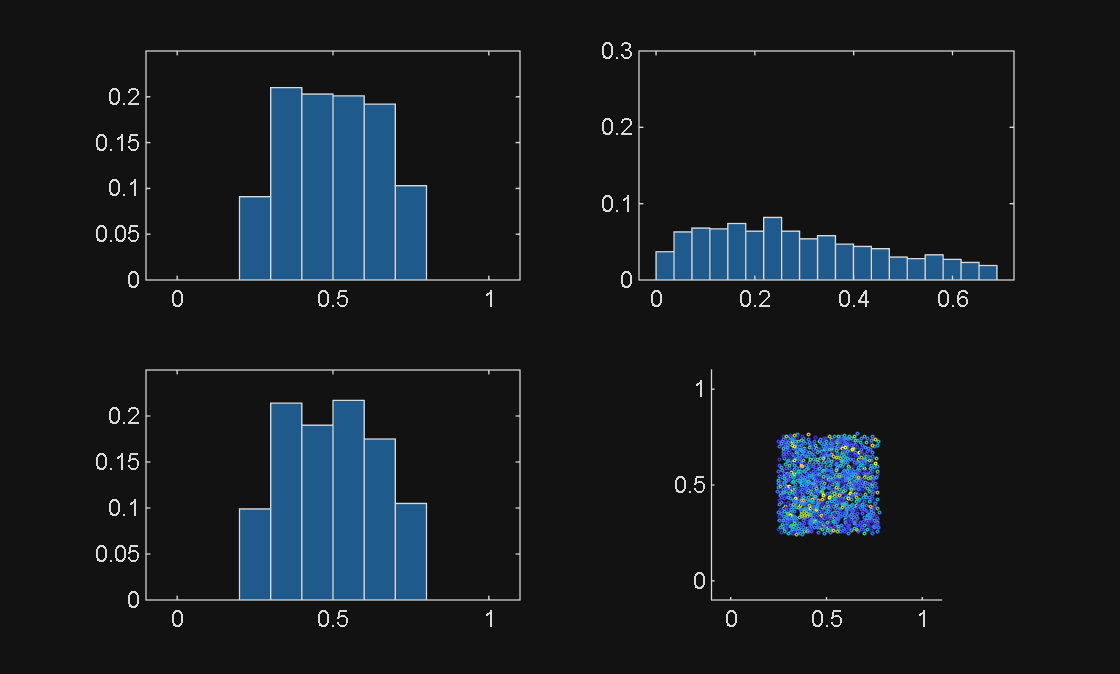

Ndim = 1000;
Tdim = 500;
dt =  .01;

T = @(A) pagetranspose(A);

r = .01;
R = .25+.5*rand(Ndim,1,2);
V = rand(Ndim,1,2);
V(:,:,2) = 0;
OP = ones(1,Ndim,1);


subplot(2,2,2)
H1 = histogram(sum(V.^2,3),0:10/30:10,Normalization='probability');
ylim([0 .3])
subplot(2,2,1)
H2 = histogram(R(:,1,1),0:1/10:1,Normalization='probability');
xlim([-.1 1.1])
ylim([0 .25])
subplot(2,2,3)
H3 = histogram(R(:,1,2),0:1/10:1,Normalization='probability');
xlim([-.1 1.1])
ylim([0 .25])
subplot(2,2,4)
S1 = scatter(R(:,1,1),R(:,1,2),1);
axis square
xlim([-.1 1.1])
ylim([-.1 1.1])
drawnow;
for i=1:500

R = mod(R,1);
    

C = sparse(vecnorm((R.*OP)-T(R.*OP),2,3)-(1-eye(Ndim))*2*r<0);

PMRx = sparse(C.*((R(:,:,1).*OP)-T(R(:,:,1).*OP)));
PMRy = sparse(C.*((R(:,:,2).*OP)-T(R(:,:,2).*OP)));

PMRMs = sqrt(PMRx.^2+PMRy.^2);

PMRx = PMRx./PMRMs;
PMRy = PMRy./PMRMs;

[Xc,Yc] = find(triu(C));

% V12 = V(Xc,:)-V(Yc,:);
% nhat = [PMRx(sub2ind(size(PMRx),Xc,Yc)) PMRy(sub2ind(size(PMRy),Xc,Yc))];
% PD = sum(V12.*nhat,2).*nhat;
% V(Xc,:) = V(Xc,:) - PD;
% V(Yc,:) = V(Yc,:) + PD;
% R12 = .5*nhat.*(PMRMs(sub2ind(size(PMRMs),Xc,Yc))-2*r);
% R(Xc,:) = R(Xc,:) - R12;
% R(Yc,:) = R(Yc,:) + R12;

for Jb=1:numel(Xc)
V12 = V(Xc(Jb),:)-V(Yc(Jb),:);
nhat = [PMRx(sub2ind(size(PMRx),Xc(Jb),Yc(Jb))) PMRy(sub2ind(size(PMRy),Xc(Jb),Yc(Jb)))];
PD = sum(V12.*nhat,2).*nhat;
V(Xc(Jb),:) = V(Xc(Jb),:) - PD;
V(Yc(Jb),:) = V(Yc(Jb),:) + PD;
R12 = .5*nhat.*(PMRMs(sub2ind(size(PMRMs),Xc(Jb),Yc(Jb)))-2*r);
R(Xc(Jb),:) = R(Xc(Jb),:) - R12;
R(Yc(Jb),:) = R(Yc(Jb),:) + R12;
end

R = R + dt*V;
RA = clip(R,r,1-r)-R;
I = any(RA,3);
RA = RA(I,:);
RA = RA./vecnorm(RA,2,2);
V(I,:) = V(I,:)-2*sum(V(I,:).*RA,3).*RA;
R = clip(R,r,1-r);


set(S1, 'XData', R(:,1,1), 'YData', R(:,1,2),'CData',clip(sum(V.^2,3),0,1));
set(H1,'Data',sum(V.^2,3))
set(H1,"BinLimits",[0 prctile(sum(V.^2,3),90)*1.1])
set(H1,"BinEdges",linspace(0,prctile(sum(V.^2,3),50)*2.5,20))
set(H2,'Data',   R(:,1,1))
set(H3,'Data',   R(:,1,2))
drawnow;
end